**PHASE 1: PREPARATION & CORRECTIONS**

     Goal: Load Sentinel-2 bands, resample all to 10 m grid, radiometrically harmonize T2 to T1,

               and co-register T2 to T1 (pixel-accurate alignment) to avoid false change detections.

     Inputs:  ONERA S2 folders (T1/T2), Sentinel-2 band files (B01...B12), cityName.

     Outputs: Cube_T1_Corr (HxWxB), Cube_T2_Reg (HxWxB), PC1_T1 (HxW), PC1_T2 (HxW), tform (translation)   

     Assumptions: ONERA "rectified" products → residual misalignment is mainly translation (no rotation/scale).

**1.1. City & band selection**

     Goal: Select city subset and define the list/order of spectral bands to load.

     Inputs:  cityName (string), bandList (1xB cell array of filenames).

     Outputs: cityName, bandList.

     Assumptions: Band files exist under imgs_1_rect / imgs_2_rect with the same names.

% 13 cities available in the dataset
cityName = "dubai";

% Sentinel-2 bands (mixed native resolutions)
bandList = {'B01.tif', 'B02.tif', 'B03.tif', 'B04.tif', 'B05.tif', ...
            'B06.tif', 'B07.tif', 'B08.tif', 'B8A.tif', 'B09.tif', ...
            }; %'B10.tif', 'B11.tif', 'B12.tif'

fprintf('[Phase1] Processing city: %s\n', cityName);

[Phase1] Processing city: dubai


**1.2. Load data cubes and resample to a common 10 m grid**

     Goal: Build spectral cubes where all bands share the same spatial grid (10 m reference).

     Inputs:  path_T1, path_T2 (folders), bandList (B bands).

     Outputs: Cube_T1_Raw, Cube_T2_Raw (HxWxB, double).

     Assumptions: Use B02 (10 m) as reference size; other bands are bicubically resampled.

baseDir = 'Onera Satellite Change Detection dataset - Images'; 

path_T1 = fullfile(baseDir, cityName, 'imgs_1_rect');
path_T2 = fullfile(baseDir, cityName, 'imgs_2_rect');

Cube_T1_Raw = loadAndResizeCube(path_T1, bandList);
Cube_T2_Raw = loadAndResizeCube(path_T2, bandList);

   Visualization: quick sanity check

fprintf('[Phase1] Data loaded. Cube size: %dx%dx%d\n', size(Cube_T1_Raw));

[Phase1] Data loaded. Cube size: 774x634x10


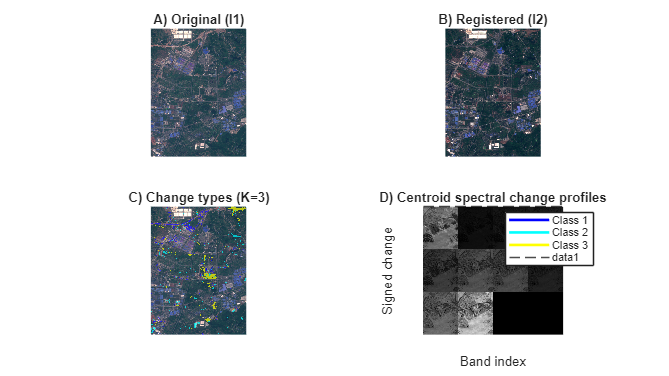


% RGB képek előkészítése
path_I1 = fullfile(baseDir, cityName, 'pair', 'img1.png');
path_I2 = fullfile(baseDir, cityName, 'pair', 'img2.png');

I1=imread(path_I1);
I2=imread(path_I2);

bands = 1:length(bandList);  
imgs = arrayfun(@(k) im2uint8(mat2gray(Cube_T1_Raw(:,:,k))), bands, 'UniformOutput', false);
imgs = cat(4, imgs{:});
montage(imgs)

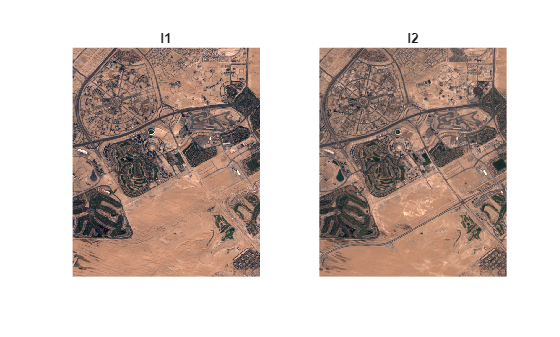


figure;
subplot(1,2,1);
imshow(I1);
title('I1');

subplot(1,2,2);
imshow(I2);
title('I2');

 1.**3. Radiometric correction — histogram matching (T2 → T1 per band)**

     Goal: Reduce illumination/atmospheric differences between dates by matching T2 band histograms to T1.

     Inputs:  Cube_T1_Raw, Cube_T2_Raw (HxWxB).

     Outputs: Cube_T1_Corr, Cube_T2_Corr (HxWxB), normalized to [0,1] for T1 reference.

     Assumptions:

           - T1 is the radiometric reference.

           - Histogram matching is applied per band (no cross-band coupling).

           - This corrects global/statistical differences, not geometry.

Cube_T1_Corr = zeros(size(Cube_T1_Raw));
Cube_T2_Corr = zeros(size(Cube_T2_Raw));

fprintf('[Phase1] Radiometric correction: histogram matching (T2 -> T1)...\n');

[Phase1] Radiometric correction: histogram matching (T2 -> T1)...



for i = 1:length(bandList)
    Ref_Band = mat2gray(Cube_T1_Raw(:,:,i)); % Reference band (T1) normalized to [0,1]
    Cube_T1_Corr(:,:,i) = Ref_Band;
    Cube_T2_Corr(:,:,i) = imhistmatch(Cube_T2_Raw(:,:,i), Ref_Band); % Match T2 histogram to the T1 reference distribution (per band)
end

fprintf('[Phase1] Radiometric correction done.\n'); 

[Phase1] Radiometric correction done.


**1.4. Co-registration (T2 → T1) using PC1 images**

     Goal: Align T2 to T1 spatially (pixel-accurate) to suppress false changes at edges.

     Inputs:  Cube_T1_Corr, Cube_T2_Corr (HxWxB).

     Outputs: Cube_T2_Reg (HxWxB), tform (translation), PC1_T1/PC1_T2 (HxW).

     Assumptions:

           - Residual misalignment is predominantly translation (ONERA rectified).

           - PC1 provides a stable, high-contrast single-channel image for registration.

fprintf('[Phase1][Coreg] Computing PCA (PC1) for registration...\n');

[Phase1][Coreg] Computing PCA (PC1) for registration...



[H, W, B] = size(Cube_T1_Corr);
X1 = reshape(Cube_T1_Corr, H*W, B); % X1/2: (H*W)xB, each row is a pixel spectrum
X2 = reshape(Cube_T2_Corr, H*W, B);

[~, score1] = pca(X1, 'NumComponents', 1); % PCA → first component only (PC1)
[~, score2] = pca(X2, 'NumComponents', 1);

PC1_T1 = reshape(score1, H, W);  % Reshape PC1 scores back into 2D images for registration
PC1_T2 = reshape(score2, H, W);

[optimizer, metric] = imregconfig('monomodal'); % Registration configuration
tform = imregtform(PC1_T2, PC1_T1, 'translation', optimizer, metric); % Estimate translation that maps PC1_T2 onto PC1_T1

fprintf('[Phase1][Coreg] Estimated translation: X=%.2f, Y=%.2f pixel\n', tform.T(3,1), tform.T(3,2));

[Phase1][Coreg] Estimated translation: X=-0.26, Y=-0.23 pixel



R = imref2d(size(PC1_T1)); % Apply the same transform to the full T2 cube
Cube_T2_Reg = imwarp(Cube_T2_Corr, tform, 'OutputView', R);

Co-registration check

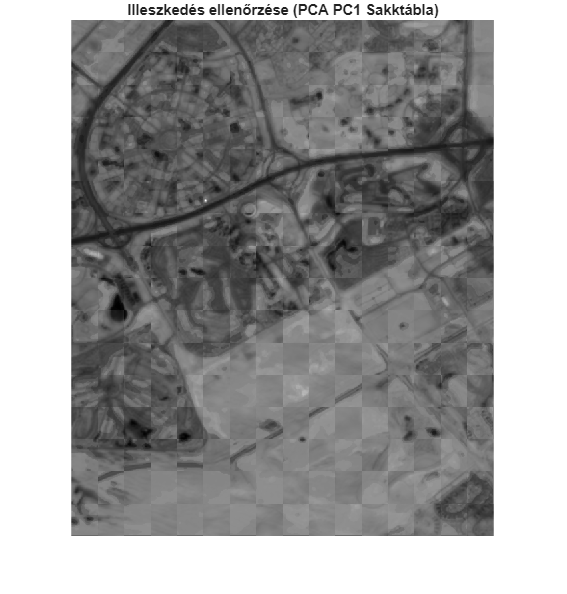

figure; 
imshowpair(PC1_T1, imwarp(PC1_T2, tform, 'OutputView', R), 'checkerboard');
title('Illeszkedés ellenőrzése (PCA PC1 Sakktábla)');

**loadAndResizeCube function**

function cube = loadAndResizeCube(folder, bands)
    % Goal: Load all requested bands from a folder and resample them to the B02 (10 m) reference grid.
    % Inputs: folder (path), bands (1xB cell array of filenames).
    % Outputs: cube (HxWxB double).
    % Assumptions:
    % - B02.tif exists and defines the target spatial size (10 m grid).
    % - Missing band files are skipped silently.
    cube = [];

    refImgPath = fullfile(folder, 'B02.tif');
    refImg = imread(refImgPath);
    [refH, refW] = size(refImg);
    
    for k = 1:length(bands)
        fname = fullfile(folder, bands{k});

        if exist(fname, 'file')
            img = im2double(imread(fname));

            if size(img,1) ~= refH
                img = imresize(img, [refH, refW], 'bicubic');
            end
            cube = cat(3, cube, img);
        end
    end
end

**PHASE 2 — CHANGE LOCALIZATION (binary mask)**

     Goal: Produce a binary change mask (binaryMask) indicating where significant changes occurred

               between T1 and T2, using a hybrid of:

       (i) PCA on the per-pixel spectral difference (intensity/structure changes), and

       (ii) SAM (spectral angle) for material/spectral-shape changes (more illumination-robust).

 Inputs:  Cube_T1_Corr (HxWxB), Cube_T2_Reg (HxWxB) from Phase 1.

 Outputs: binaryMask (HxW logical), plus diagnostic maps: pcaMap, samMap, fusionMap in [0,1].

 Assumptions: 

  - Cubes are already radiometrically harmonized (T2 → T1) and co-registered (pixel-aligned).

   - pcaMap and samMap are normalized to [0,1], so linear fusion is meaningful.

   - Otsu thresholding is suitable for separating background vs change responses.

**2.1. User interactive controls**

     Goal: Tune sensitivity and fusion behavior without modifying algorithmic structure.

     Inputs:  sensitivity, useFilter, weightPCA.

     Outputs: affects final binaryMask (threshold strictness, denoising, PCA-vs-SAM balance).

     Assumptions:

           - sensitivity scales the automatic Otsu threshold (1.0 = default).

           - weightPCA in [0,1]: higher emphasizes PCA-diff (intensity/structure), lower emphasizes SAM (material).

% Sensitivity (threshold multiplier).
% < 1.0: more permissive (more pixels flagged as change)
% > 1.0: more strict (only strong changes)
sensitivity = 1.2 

sensitivity = 1.2000


% Spatial denoising switch (median filter on fusion map)
useFilter = true 

useFilter = logical
   1



% Fusion weight: PCA vs SAM (0..1)
% >0.5: emphasize intensity/structure changes (e.g., construction, roads)
% <0.5: emphasize spectral-shape/material changes (e.g., surface type), more shadow-robust
weightPCA = 0.5

weightPCA = 0.5000


fprintf('[Phase2] Hybrid change detection (weightPCA=%.2f, weightSAM=%.2f)\n', weightPCA, 1-weightPCA);

[Phase2] Hybrid change detection (weightPCA=0.50, weightSAM=0.50)


**2.2. PCA Difference Map (structure / intensity-driven change)**

     Goal: Build a single-channel change magnitude map from multi-band absolute differences.

     Inputs:  Cube_T1_Corr (HxWxB), Cube_T2_Reg (HxWxB).

     Outputs: pcaMap in [0,1] (HxW).

     Assumptions:

           - Use absolute difference: direction (brighter/darker) is ignored at this stage; only magnitude matters.

           - PC1 captures the dominant mode of spectral change across bands.

           - 99th percentile clipping reduces outlier dominance before min–max normalization.

fprintf('[Phase2][PCA-diff] Computing PCA on absolute spectral differences...\n');

[Phase2][PCA-diff] Computing PCA on absolute spectral differences...


diffCube = abs(Cube_T1_Corr - Cube_T2_Reg);
[H, W, B] = size(diffCube);

X_Diff = reshape(diffCube, H*W, B);
[~, scoreDiff] = pca(X_Diff, 'NumComponents', 1);
pcaMapRaw = abs(reshape(scoreDiff(:,1), H, W)); 

% Why percentile clipping: a few extreme pixels can compress the dynamic range after min–max scaling
p99_pca = prctile(pcaMapRaw(:), 99);
pcaMap = min(pcaMapRaw, p99_pca);

% Normalize to [0,1] for fusion and thresholding
pcaMap = (pcaMap - min(pcaMap(:))) / (max(pcaMap(:)) - min(pcaMap(:)));

**2.3. SAM Map (material / spectral-shape change; illumination-robust)**

     Goal: Compute spectral angle between T1 and T2 spectra per pixel (shape similarity).

     Inputs:  Cube_T1_Corr (HxWxB), Cube_T2_Reg (HxWxB).

     Outputs: samMap in [0,1] (HxW).

     Assumptions:

           - SAM uses the angle between spectral vectors: more robust to global brightness scaling.

           - eps avoids division by zero for near-zero norms.

           - 99th percentile clipping improves robustness before min–max normalization.

fprintf('[Phase2][SAM] Computing Spectral Angle Mapper...\n');

[Phase2][SAM] Computing Spectral Angle Mapper...



dotProd = sum(Cube_T1_Corr .* Cube_T2_Reg, 3); % dot product and norms per pixel (HxW)
norm1 = sqrt(sum(Cube_T1_Corr.^2, 3));
norm2 = sqrt(sum(Cube_T2_Reg.^2, 3));

samMapRaw = acos(dotProd ./ (norm1 .* norm2 + eps)); % Spectral angle (radians)
samMapRaw(isnan(samMapRaw)) = 0; 
samMapRaw = real(samMapRaw);

p99_sam = prctile(samMapRaw(:), 99); % Percentile clipping + normalization to [0,1]
samMap = min(samMapRaw, p99_sam);
samMap = (samMap - min(samMap(:))) / (max(samMap(:)) - min(samMap(:)));

**2.4. Hybrid fusion + optional spatial denoising**

     Goal: Fuse PCA-diff and SAM maps into a single change likelihood map and optionally denoise it.

     Inputs:  pcaMap, samMap in [0,1].

     Outputs: fusionMap in [0,1] (HxW).

     Assumptions:

           - Linear fusion is meaningful because both maps are normalized to the same range.

           - Median filtering reduces salt-and-pepper artifacts while preserving edges.

fprintf('[Phase2] Fusing maps and applying optional denoising...\n');

[Phase2] Fusing maps and applying optional denoising...



fusionMap = (weightPCA * pcaMap) + ((1-weightPCA) * samMap);

if useFilter
    fusionMap = medfilt2(fusionMap, [3 3]);
end

fusionMap = (fusionMap - min(fusionMap(:))) / (max(fusionMap(:)) - min(fusionMap(:)));

**2.5. Thresholding (Otsu) + binary mask cleanup**

     Goal: Convert fusionMap to a binary change mask using automatic thresholding and small-object removal.

     Inputs:  fusionMap in [0,1], sensitivity.

     Outputs: binaryMask (HxW logical).

     Assumptions:

           - Otsu (graythresh) separates background vs change responses reasonably.

           - sensitivity scales threshold for user-controlled strictness.

           - bwareaopen removes tiny connected components (noise).

fprintf('[Phase2] Thresholding (Otsu) and mask cleanup...\n');

[Phase2] Thresholding (Otsu) and mask cleanup...



baseThresh = graythresh(fusionMap); % Otsu threshold on [0,1] map
finalThresh = baseThresh * sensitivity;

binaryMask = fusionMap > finalThresh; 

% Remove very small detections (noise)
% Why 5 px: suppress isolated tiny components that are unlikely to be meaningful changes
binaryMask = bwareaopen(binaryMask, 5); 

fprintf('[Phase2] Detected change: %.2f%% of pixels (threshold=%.4f)\n', mean(binaryMask(:))*100, finalThresh);

[Phase2] Detected change: 6.06% of pixels (threshold=0.4282)


Visualization

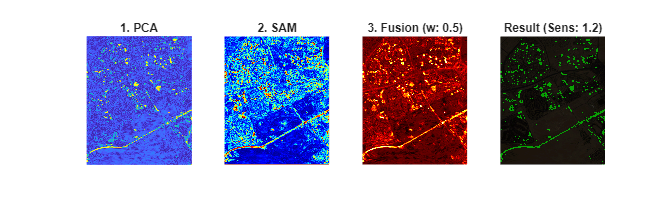

figure('Name', 'Interaktív Eredmény', 'Units', 'normalized', 'Position', [0.1 0.1 0.9 0.5]);

% 1. PCA map
subplot(1, 4, 1); 
imshow(pcaMap, []); colormap(gca, 'parula'); title('1. PCA');

% 2. SAM map
subplot(1, 4, 2); 
imshow(samMap, []); colormap(gca, 'jet'); title('2. SAM');

% 3. Fusion map
subplot(1, 4, 3); 
imshow(fusionMap, []); colormap(gca, 'hot'); 
title(sprintf('3. Fusion (w: %.1f)', weightPCA));

% 4. Final overlay
subplot(1, 4, 4);

rgb = cat(3, Cube_T2_Reg(:,:,4), Cube_T2_Reg(:,:,3), Cube_T2_Reg(:,:,2));
imshow(rgb); hold on;

% Green mask
greenLayer = cat(3, zeros(size(binaryMask)), ones(size(binaryMask)), zeros(size(binaryMask)));
h = imshow(greenLayer);
set(h, 'AlphaData', binaryMask * 0.6); 
title(sprintf('Result (Sens: %.1f)', sensitivity));

**PHASE 3 — CHANGE TYPE CLASSIFICATION (K-MEANS CLUSTERING)**

     Goal: Classify detected change pixels (binaryMask) into K change "types" using K-means.

               Each changed pixel is represented by its signed spectral difference vector (T2 − T1).

     Inputs:  Cube_T1_Corr (HxWxB), Cube_T2_Reg (HxWxB), binaryMask (HxW), I1/I2 (for visualization).

     Outputs: clusterMap (HxW, labels 0..K), idx (N x 1), centroids C (K x B).

     Assumptions:

           - binaryMask isolates meaningful change locations (Phase 2).

           - Signed difference captures direction (brightening vs darkening), useful for clustering.

           - Euclidean K-means provides stable grouping in urban scenes (practical choice).

**3.1. Feature extraction: signed spectral change vectors**

         Goal: Build a feature matrix for clustering: per changed pixel, per band change (T2 − T1).

         Inputs:  Cube_T2_Reg, Cube_T1_Corr, binaryMask.

         Outputs: changeVectors (N_change x B).

         Assumptions:

               - Cubes are aligned (Phase 1) and radiometrically harmonized (Phase 1).

               - Using signed diffs preserves change direction.

fprintf('[Phase3] Change-type analysis via standard K-means...\n');

[Phase3] Change-type analysis via standard K-means...



numClasses =3; 

[row, col] = find(binaryMask); 

fprintf('[Phase3] %d changed pixels found. Extracting features...\n', length(row));

[Phase3] 29759 changed pixels found. Extracting features...



diffCubeSigned = Cube_T2_Reg - Cube_T1_Corr; 
    
changeVectors = zeros(length(row), size(diffCubeSigned, 3));
for k = 1:size(diffCubeSigned, 3)
    band = diffCubeSigned(:,:,k);
    changeVectors(:,k) = band(binaryMask);
end

** 3.2. K-means clustering (standard Euclidean)**

         Goal: Partition changeVectors into K groups by minimizing within-cluster Euclidean distances.

         Inputs: changeVectors (N x B), numClasses (K).

        Outputs: idx (N x 1 cluster labels), C (K x B centroids).

         Assumptions:

               - Euclidean distance is a reasonable similarity measure for signed change vectors.

               - Multiple replicates reduce sensitivity to random initialization.

         Notes:

               - rng(42) fixes random seed → reproducible clusters.


    fprintf('[Phase3][KMeans] Running K-means (K=%d)...\n', numClasses);

[Phase3][KMeans] Running K-means (K=3)...



    rng(42); 
    
    try
        [idx, C] = kmeans(changeVectors, numClasses, 'Replicates', 3, 'MaxIter', 100);
        
        clusterMap = zeros(size(binaryMask));
        for i = 1:length(row)
            clusterMap(row(i), col(i)) = idx(i);
        end
        
        fprintf('[Phase3][KMeans] Success. %d pixels clustered.\n', length(row));

    catch ME          % Goal: Prevent pipeline failure if clustering errors occur (e.g., degenerate data).
        fprintf('[Phase3][KMeans] ERROR: %s\n', ME.message);
        clusterMap = binaryMask; % Fallback
        C = []; 
    end

[Phase3][KMeans] Success. 29759 pixels clustered.


Visualization

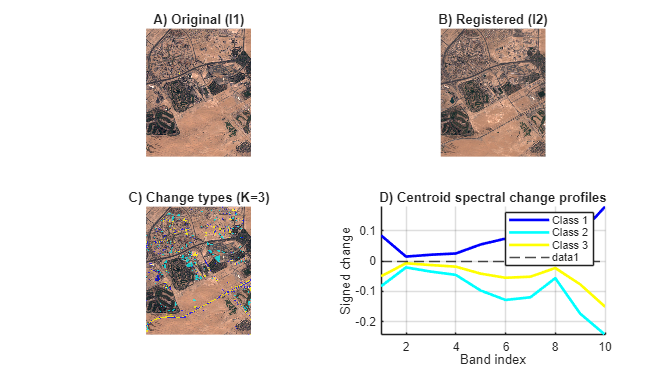

    figure('Name', '[Phase3] K-means change types', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);
    
    clusterColors = jet(numClasses); 

    % A) Original image I1
    subplot(2, 2, 1);

    imshow(I1); title('A) Original (I1)');
    
    % B) Registered image I2
    subplot(2, 2, 2);
    imshow(I2); title('B) Registered (I2)');
    
    % C) Clustered change map overlay
    subplot(2, 2, 3);
    imshow(I1); hold on;
    
    if max(clusterMap(:)) > 0
        coloredLabels = label2rgb(clusterMap, clusterColors, 'k', 'shuffle');
        h2 = imshow(coloredLabels);
        set(h2, 'AlphaData', binaryMask * 0.7); 
        title(sprintf('C) Change types (K=%d)', numClasses));
    else
        title('No data');
    end
    
    % D) Centroid change profiles across bands
    subplot(2, 2, 4);

    if ~isempty(C)
        hold on; grid on;

        for c = 1:numClasses
            plot(C(c,:), 'LineWidth', 2, 'Color', clusterColors(c,:), 'DisplayName', sprintf('Class %d', c));
        end
        
        yline(0, 'k--'); 
        legend('Location', 'best');
        title('D) Centroid spectral change profiles');
        xlabel('Band index'); ylabel('Signed change');
        axis tight;
    else
        text(0.5, 0.5, 'Clustering failed (no centroids)', 'HorizontalAlignment', 'center');
    end